clear all 
close all 
clc

T = readtable('power_cons_20160101_20181231.csv', 'HeaderLines',1)

T = 52608×5 table
                Var1                    Var2         Var3       Var4          Var5      
    _____________________________    __________    _________    _____    _______________

    {'2016-01-01T00:00:00+01:00'}    01/01/0016    {'00:00'}    60165    {'DÌ©finitive'}
    {'2016-01-01T00:30:00+01:00'}    01/01/0016    {'00:30'}    58887    {'DÌ©finitive'}
    {'2016-01-01T01:00:00+01:00'}    01/01/0016    {'01:00'}    56678    {'DÌ©finitive'}
    {'2016-01-01T01:30:00+01:00'}    01/01/0016    {'01:30'}    56460    {'DÌ©finitive'}
    {'2016-01-01T02:00:00+01:00'}    01/01/0016    {'02:00'}    55780    {'DÌ©finitive'}
    {'2016-01-01T02:30:00+01:00'}    01/01/0016    {'02:30'}    55233    {'DÌ©finitive'}
    {'2016-01-01T03:00:00+01:00'}    01/01/0016    {'03:00'}    53160    {'DÌ©finitive'}
    {'2016

dateheure = table2array(T(:,1))

dateheure = 52608×1 cell array
    {'2016-01-01T00:00:00+01:00'}
    {'2016-01-01T00:30:00+01:00'}
    {'2016-01-01T01:00:00+01:00'}
    {'2016-01-01T01:30:00+01:00'}
    {'2016-01-01T02:00:00+01:00'}
    {'2016-01-01T02:30:00+01:00'}
    {'2016-01-01T03:00:00+01:00'}
    {'2016-01-01T03:30:00+01:00'}
    {'2016-01-01T04:00:00+01:00'}
    {'2016-01-01T04:30:00+01:00'}
    {'2016-01-01T05:00:00+01:00'}
    {'2016-01-01T05:30:00+01:00'}
    {'2016-01-01T06:00:00+01:00'}
    {'2016-01-01T06:30:00+01:00'}
    {'2016-01-01T07:00:00+01:00'}
    {'2016-01-01T07:30:00+01:00'}
    {'2016-01-01T08:00:00+01:00'}
    {'2016-01-01T08:30:00+01:00'}
    {'2016-01-01T09:00:00+01:00'}
    {'2016-01-01T09:30:00+01:00'}
    {'2016-01-01T10:00:00+01:00'}
    {'2016-01-01T10:30:00+01:00'}
    {'2016-01-01T11:00:00+01:00'}
    {'2016-01-01T11:30:00+01:00'}
    {'2016-01-01T12:00:00+01:00'}
    {'2016-01-01T12:30:00+01:00'}
    {'2016-01-01T13:00:00+01:00'}
    {'2016-01-01T13:30:00+01:00'}
    {'2016-01-01T

date = table2array(T(:,2)) 

date = 52608×1 datetime array
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016
   01/01/0016


heure = table2array(T(:,3))

heure = 52608×1 cell array
    {'00:00'}
    {'00:30'}
    {'01:00'}
    {'01:30'}
    {'02:00'}
    {'02:30'}
    {'03:00'}
    {'03:30'}
    {'04:00'}
    {'04:30'}
    {'05:00'}
    {'05:30'}
    {'06:00'}
    {'06:30'}
    {'07:00'}
    {'07:30'}
    {'08:00'}
    {'08:30'}
    {'09:00'}
    {'09:30'}
    {'10:00'}
    {'10:30'}
    {'11:00'}
    {'11:30'}
    {'12:00'}
    {'12:30'}
    {'13:00'}
    {'13:30'}
    {'14:00'}
    {'14:30'}


conso = table2array(T(:,4))

conso =        60165
       58887
       56678
       56460
       55780
       55233
       53160
       51648
       50207
       49345


## analyse temporelle

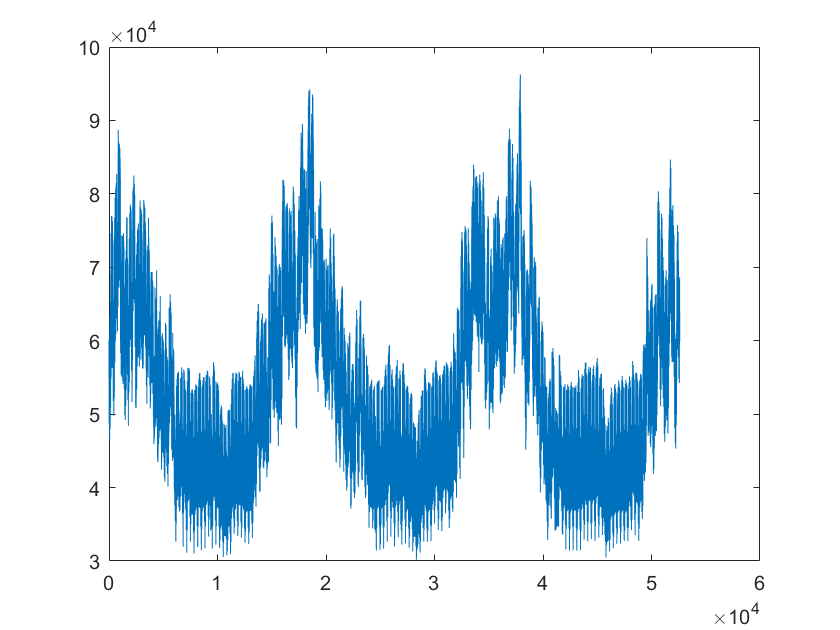


figure(1)
plot(conso)

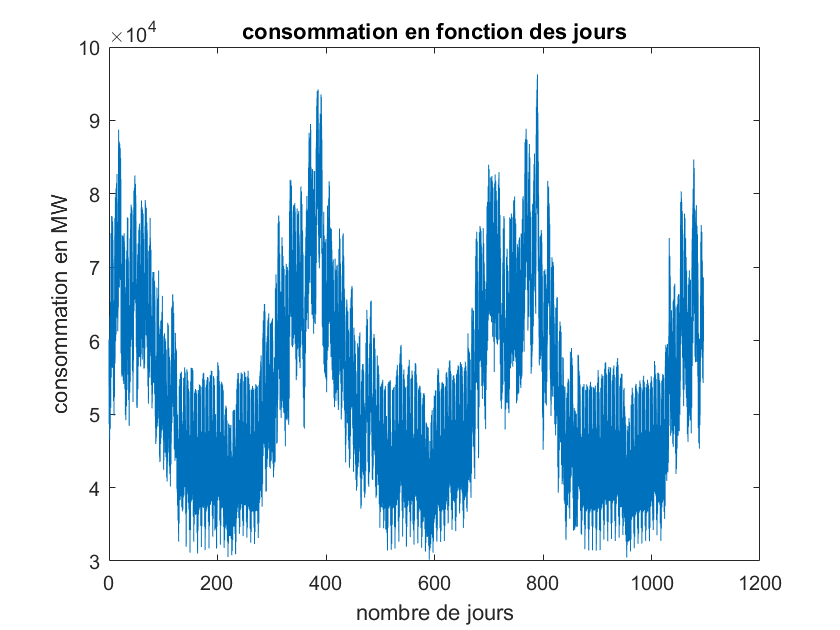


t=0:length(conso)-1 ;

Tjours=1/48 ; fjours=1/Tjours ; 
tjours = t*Tjours;
figure(2) ; plot(tjours,conso) ; title('consommation en fonction des jours') ; xlabel ('nombre de jours') ; ylabel('consommation en MW') ;

## analyse spectrale

%verif spectre
N=1000 ; n = 0 : N-1 ; fs = 400 ; t=n/fs ; f1 = 10 ; f2 = 100 ; f3 = 130

f3 = 130

s = 5*cos(f1*2*pi*t) + 4*cos(f2*2*pi*t) + 2*cos(f3*2*pi*t)

s =    11.0000    4.0305   -0.4203    6.4304    7.4271    2.1213    0.8410    1.9571    3.9271    2.5642   -4.0000   -2.5642    4.0729   -1.9571   -8.8410   -2.1213    0.5729   -6.4304   -7.5797   -4.0305   -3.0000   -4.0305   -7.5797   -6.4304    0.5729   -2.1213   -8.8410   -1.9571    4.0729   -2.5642   -4.0000    2.5642    3.9271    1.9571    0.8410    2.1213    7.4271    6.4304   -0.4203    4.0305   11.0000    4.0305   -0.4203    6.4304    7.4271    2.1213    0.8410    1.9571    3.9271    2.5642


[mods,fs]= Spectre(s,fs,1)

mods =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.5000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


fs =          0    0.4000    0.8000    1.2000    1.6000    2.0000    2.4000    2.8000    3.2000    3.6000    4.0000    4.4000    4.8000    5.2000    5.6000    6.0000    6.4000    6.8000    7.2000    7.6000    8.0000    8.4000    8.8000    9.2000    9.6000   10.0000   10.4000   10.8000   11.2000   11.6000   12.0000   12.4000   12.8000   13.2000   13.6000   14.0000   14.4000   14.8000   15.2000   15.6000   16.0000   16.4000   16.8000   17.2000   17.6000   18.0000   18.4000   18.8000   19.2000   19.6000


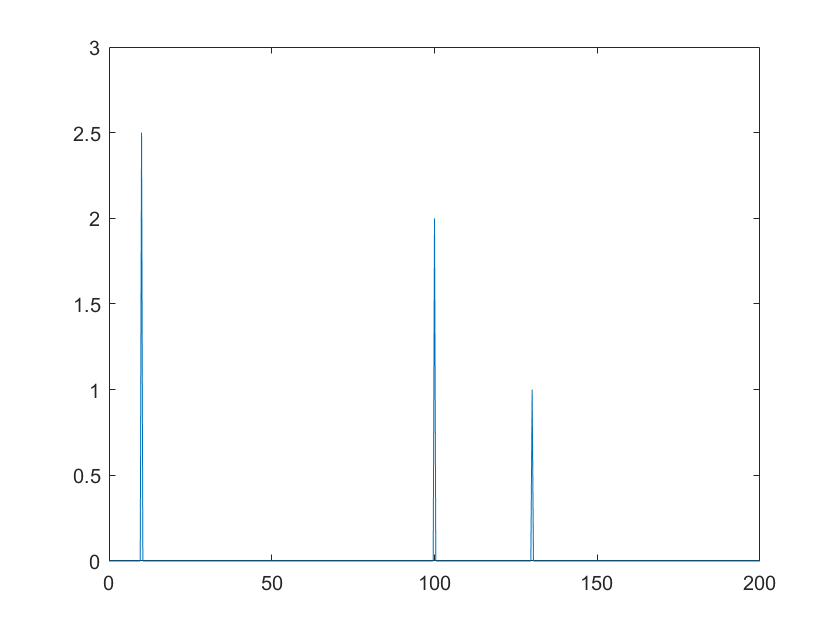

figure(4) ; plot(fs,mods)



Tannee = 1/17520 ;
fannee = 1/Tannee ;
[modconso,fconso] = Spectre(conso-mean(conso),fannee,1)

modconso = 	1.0e+03 *

    0.0000
    0.1543
    0.4603
    6.7267
    0.2805
    0.6254
    1.5408
    0.3355
    0.6774
    0.6631


fconso = 	1.0e+03 *

         0    0.0003    0.0007    0.0010    0.0013    0.0017    0.0020    0.0023    0.0027    0.0030    0.0033    0.0037    0.0040    0.0043    0.0047    0.0050    0.0053    0.0057    0.0060    0.0063    0.0067    0.0070    0.0073    0.0077    0.0080    0.0083    0.0087    0.0090    0.0093    0.0097    0.0100    0.0103    0.0107    0.0110    0.0113    0.0117    0.0120    0.0123    0.0127    0.0130    0.0133    0.0137    0.0140    0.0143    0.0147    0.0150    0.0153    0.0157    0.0160    0.0163


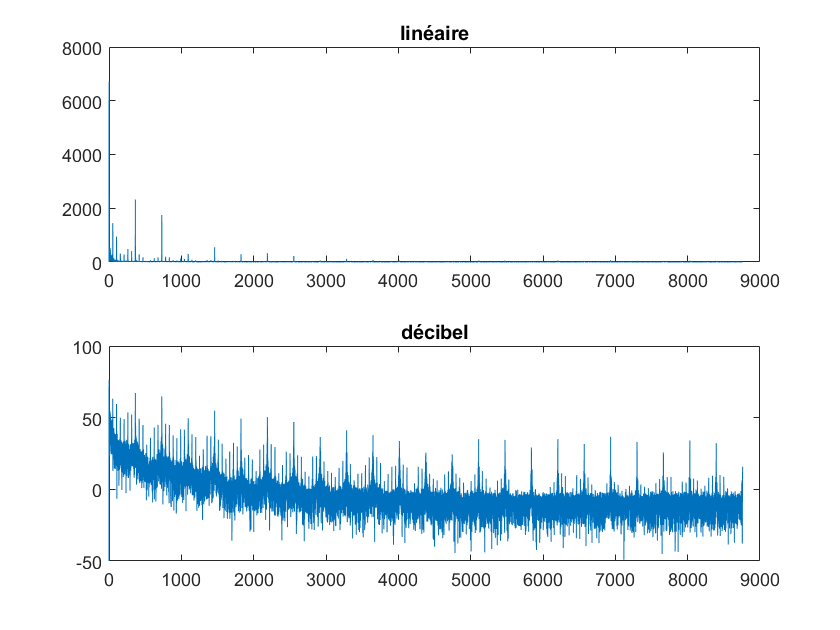

figure(3) ; subplot(211) ; plot(fconso,modconso) ; title('linéaire') ; 
subplot(212) ; plot(fconso, 20*log10(modconso)) ; ylim([-50,100]) ; title('décibel') ;

## Filtrage

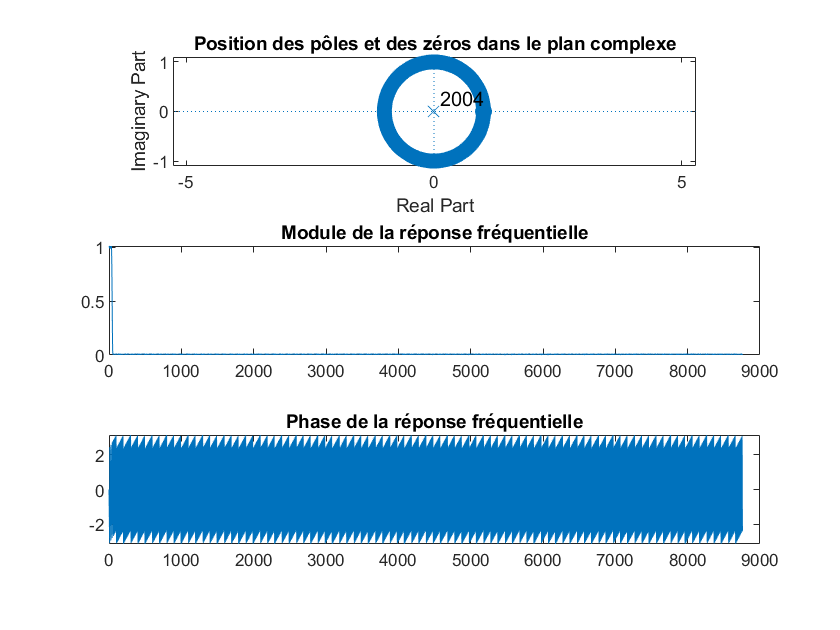

%passe bas < 52

fp=35;
fc=52;
F=[fp fc];
A1=[1 0];
DEV=0.01*[1 1];
[m,f0,ao,w]=firpmord(F,A1,DEV,fannee);
FAnn=firpm(m,f0,ao,w);
[Modf2,Phsf2,Ff2]=FilterVisu(FAnn,1,4096,fannee);% création d'un filtre passe bas

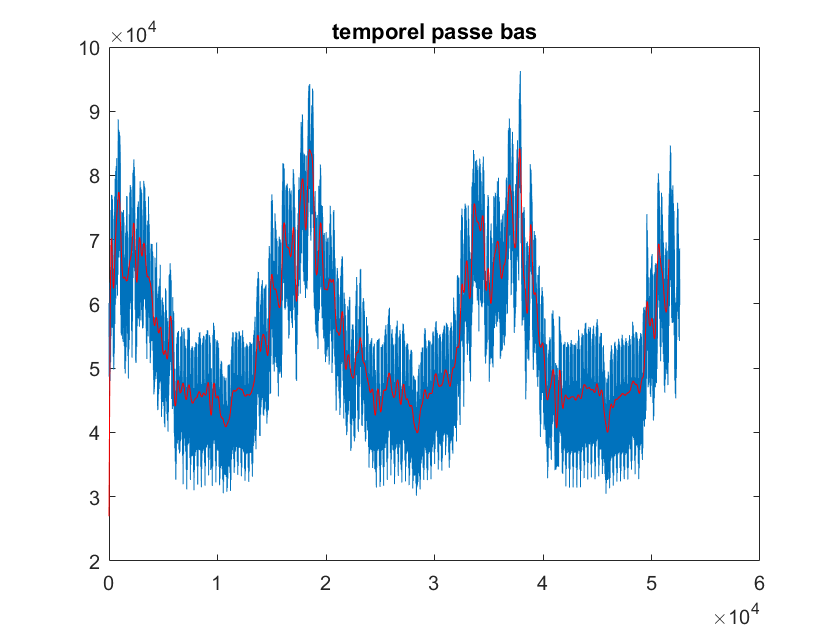


consoAnn = filter(FAnn,1,conso);

figure(5)
plot(conso);
hold on;
plot(consoAnn(1+round(m/2):end),'r');
title('temporel passe bas')

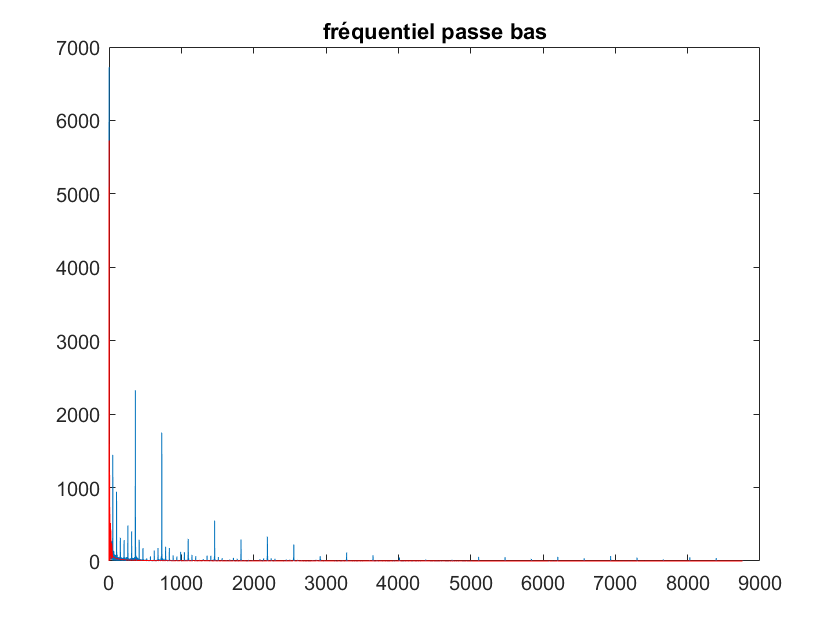


[ModAnn,FreqAnn]=Spectre(consoAnn-mean(consoAnn),fannee,1);
figure(6)
plot(fconso,modconso);
hold on;
plot(FreqAnn,ModAnn,'r');
title('fréquentiel passe bas')

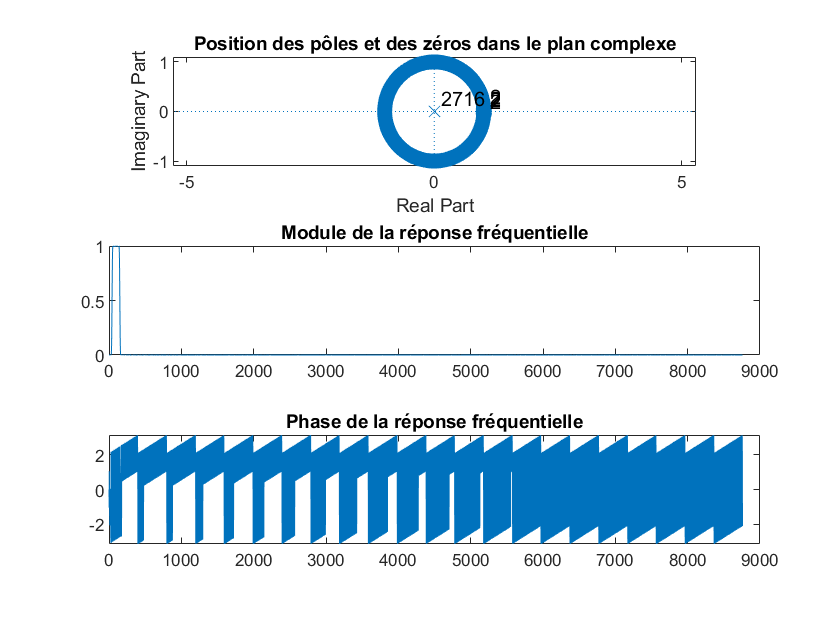


%passe bande <52>

fo1=42;
fo2=150;
Deltaf=20;
lo1=fo1/fannee;
lo2=fo2/fannee;
DeltaFnorm1=Deltaf/fannee;
M=round(3.1/DeltaFnorm1);
FHeb=fir1(M,2*[lo1 lo2]);
figure(7)
[Modf2,Phsf2,Ff2]=FilterVisu(FHeb,1,4096,fannee);

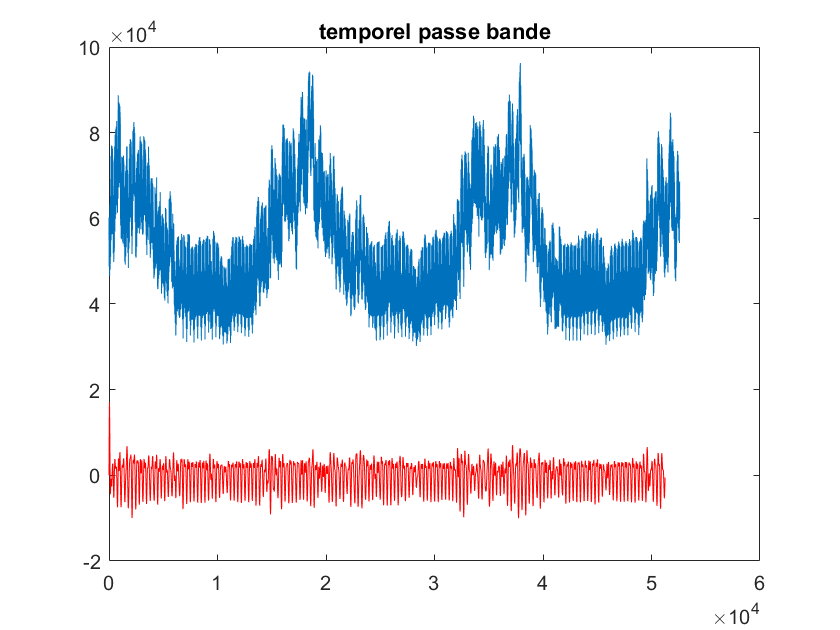

consoHeb = filter(FHeb,1,conso);

figure(8)
plot(conso);
hold on;
plot(consoHeb(1+round(M/2):end),'r');
title('temporel passe bande')

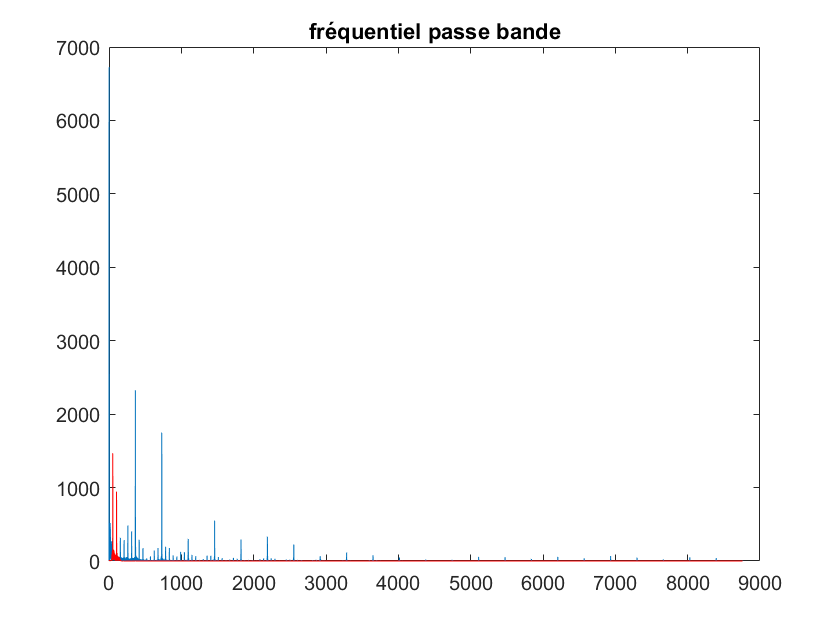


[ModHeb,FreqHeb]=Spectre(consoHeb-mean(consoHeb),fannee,1);
figure(9)
plot(fconso,modconso);
hold on;
plot(FreqHeb,ModHeb,'r');
title('fréquentiel passe bande')

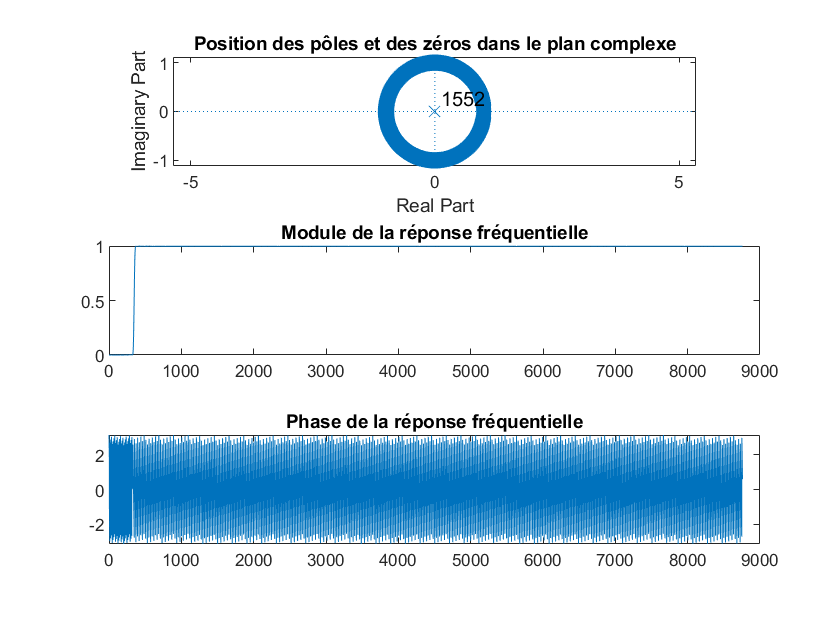


%passe haut >52

fp=330;
fc=365;
fo=(fc+fp)/2;
df=fc-fp;
Dlambda=df/fannee;
K=round(3.1/Dlambda);
FQuo=fir1(K,2*fo/fannee,'high');
figure(10)
[Modf3,Phsf3,Ff3]=FilterVisu(FQuo,1,4096,fannee);

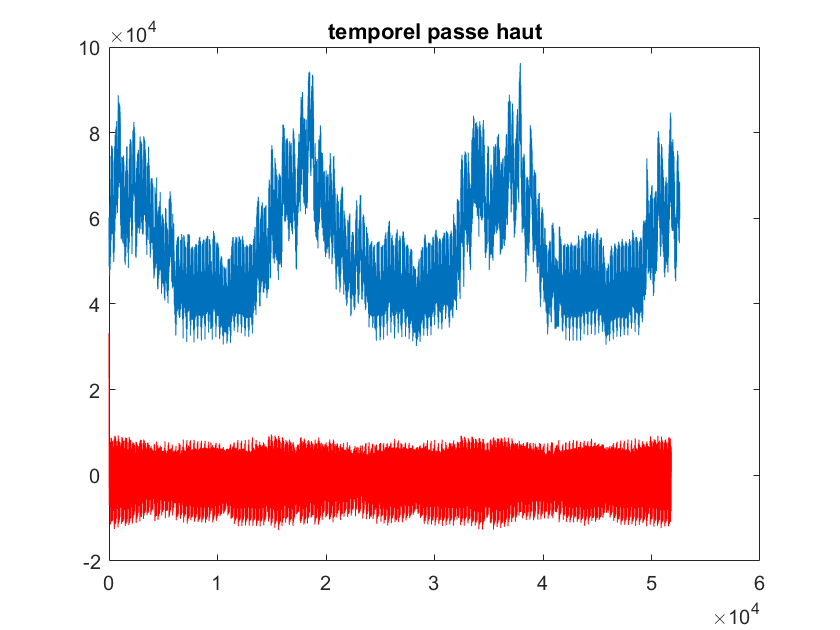


consoQuo= filter(FQuo,1,conso);

figure(11)
plot(conso);
hold on;
plot(consoQuo(1+round(K/2):end),'r');
title('temporel passe haut')

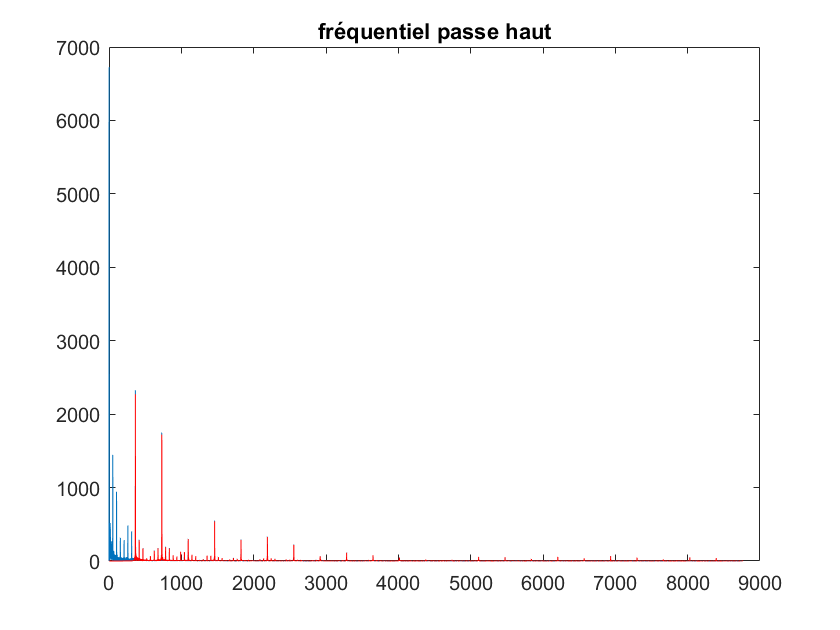


[ModQuo,FreqQuo]=Spectre(consoQuo-mean(consoQuo),fannee,1);
figure (12)
plot(fconso,modconso)
hold on;
plot(FreqQuo,ModQuo,'r');
title('fréquentiel passe haut')